# EE110B Lab 6 

# Name: Buddy Ugwumba SID: 862063029

## 1) First, determine the analytical form of $h\left\lbrack n\right\rbrack$ by performing the inverse DTFT of $H\left(f\right)$.

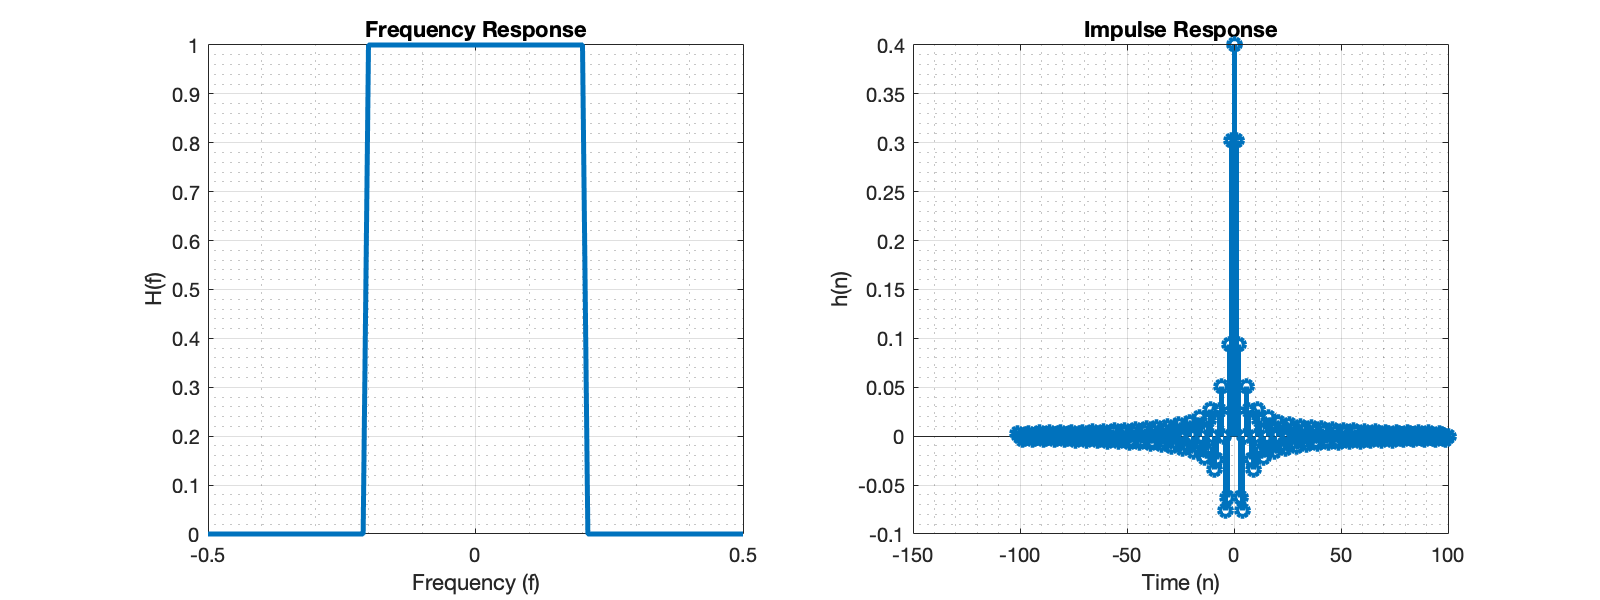

n = -101:1:100;
f_c = 0.2;
f = -0.5:0.01:0.5;
H_f = zeros(1, length(f));
H_f(-0.2 <= f) = 1;
H_f(f> 0.2) = 0;

h_n = sin(0.4*pi*n)./(n*pi);
h_n (n==0) = 0.4;

fig1 = figure(1); fig1.Position = [100 100 800 300];
subplot(1,2,1)
plot(f,abs(H_f), 'LineWidth',2.5);
xlabel('Frequency (f)');
ylabel('H(f)');
title('Frequency Response');
grid on 
grid minor
subplot(1,2,2)
stem(n,h_n,'LineWidth',2.5);
xlabel('Time (n)');
ylabel('h(n)');
title("Impulse Response")
grid on
grid minor

## 2) Second, compute $g\left\lbrack n\right\rbrack =h\left\lbrack n-n_o \right\rbrack w\left\lbrack n\right\rbrack$ where 

## 
$$w\left\lbrack n\right\rbrack =\left\lbrack \begin{array}{cc}
n & 0\le n\le n_o \\
2n_o -n & n_o \le n\le 2n_0 
\end{array}\right\rbrack$$


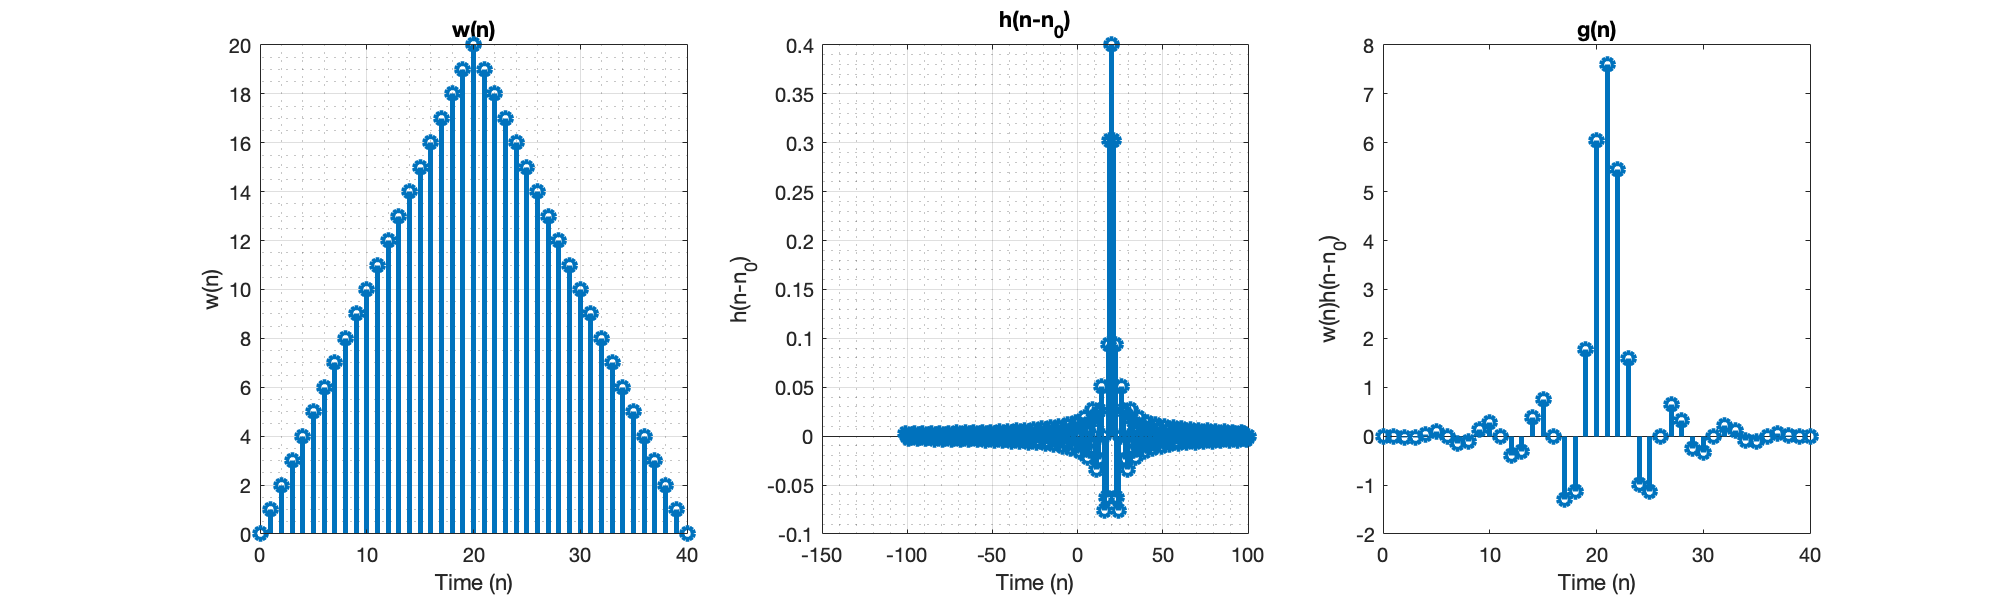

n_0 = 20;
w_n = [0:1:n_0 n_0-1:-1:0];
h_n_n_0 = [sin(0.4*pi*(n-n_0))./((n-n_0)*pi)];
h_n_n_0(n == n_0) = 0.4;
g_n = w_n.*h_n_n_0(101:101+2*n_0);

fig2 = figure(2);
fig2.Position = [100 100 1000 300];
subplot(1,3,1)
stem([0:1:2*n_0],w_n,'LineWidth',2.5);
xlabel('Time (n)');
ylabel('w(n)');
title('w(n)');
grid on
grid minor

subplot(1,3,2)
stem(n,h_n_n_0, 'LineWidth',2.5);
xlabel('Time (n)');
ylabel('h(n-n_0)');
title('h(n-n_0)');
grid on 
grid minor

subplot(1,3,3)
stem(0:2*n_0,g_n,'LineWidth',2.5);
xlabel('Time (n)');
ylabel('w(n)h(n-n_0)');
title('g(n)')

## 3) Choose different values for $n_0$ (such as 20 and 30) and compute and plot the amplitude specturm$|G\left(f\right)|$of $g_n$ for $-0\ldotp 5<f<0\ldotp 5$

## 4) Compare $|G\left(f\right)|$with $|H\left(f\right)|$and discuss the effect  of $n_o$

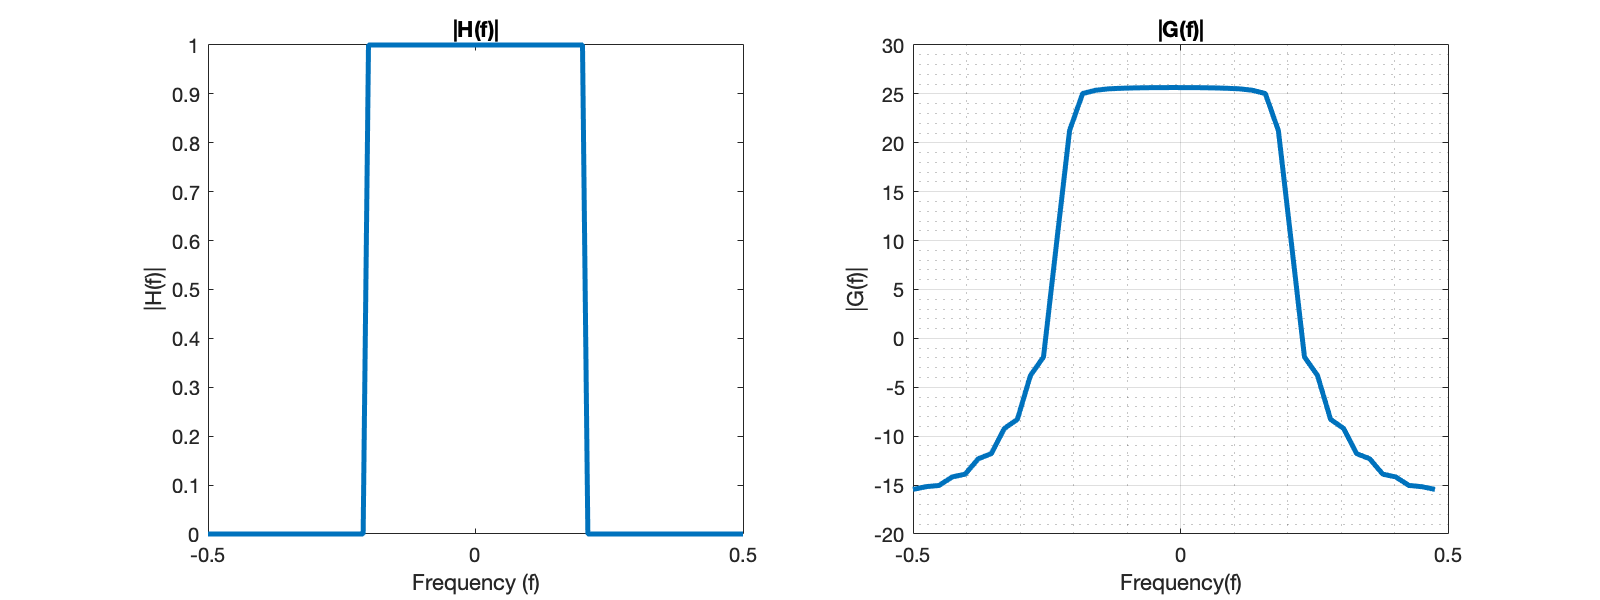

G_f = fftshift(fft(g_n));
f_g = -0.5:1/length(G_f):0.5-(1/length(G_f));
fig3 = figure(3);
fig3.Position = [100 100 800 300];
subplot(1,2,1)
plot(f,abs(H_f), 'LineWidth',2.5);
xlabel('Frequency (f)');
ylabel('|H(f)|');
title('|H(f)|')

subplot(1,2,2)
plot(f_g,20*log10(abs(G_f)),'LineWidth',2.5);
xlabel('Frequency(f)');
ylabel('|G(f)|');
title('|G(f)|');
grid on
grid minor

The effect of $n_0$ is as follows the bigger the value the more coefficents. Therefore, the filter becomes less ideal. A small value of $n_{0\;}$produces a better filter

## 5) Compute and plot the phase spectrum $\angle G\left(f\right)$ of $g_n$

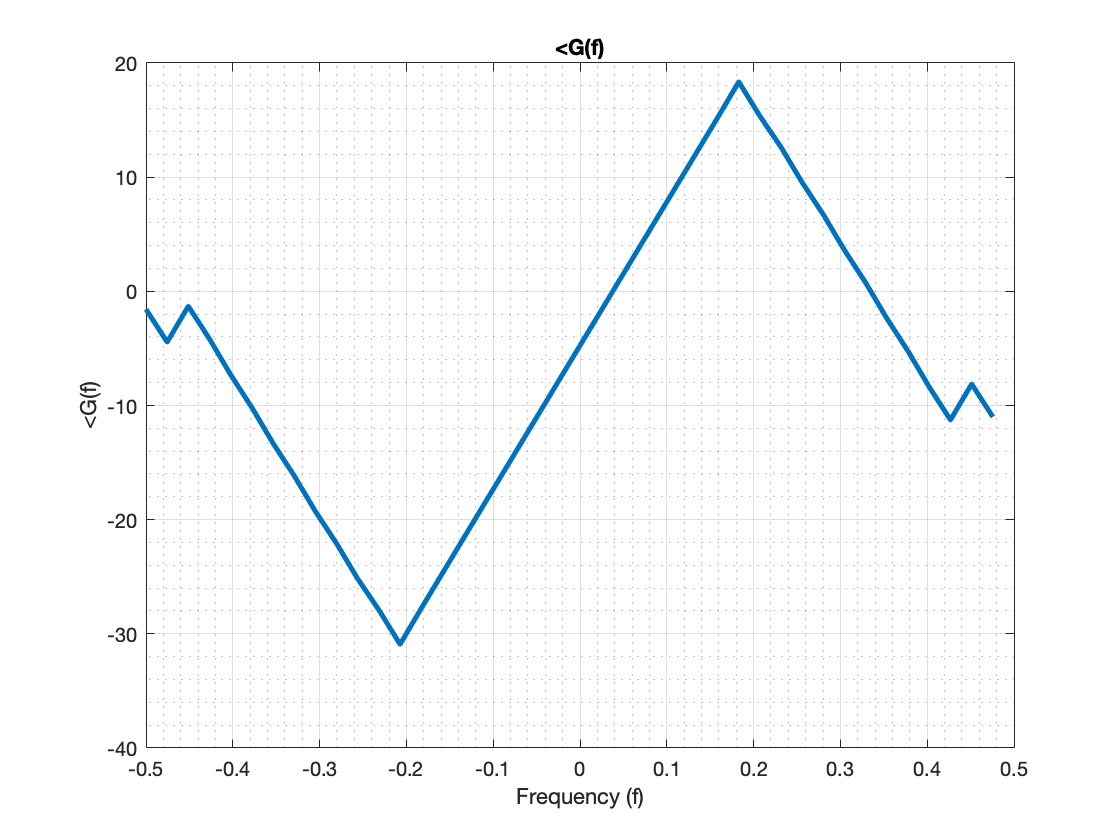

figure
plot(f_g,unwrap(angle(G_f)),'LineWidth',2.5);
grid on
grid minor
xlabel('Frequency (f)');
ylabel('<G(f)');
title('<G(f)');

## 6) What do you expect at the output

I'm sorry I just did not do my best on this lab. This week has been trying I will do better next time. 